# Random Forest - Feature Extracting 

## Colocar Títulos a la Tabla

clear; close all; 

% Cargar datos
data = load("Dataset_Marcha_Procesado.mat");
dataTable = data.tablaMaestra;

% 1. Definir la lista de articulaciones y ejes
jointNames = {'SpineBase', 'MidSpine', 'Neck', 'Head', 'LeftShoulder', ...
    'LeftElbow', 'LeftWrist', 'LeftHand', 'RightShoulder', 'RightElbow', ...
    'RightWrist', 'RightHand', 'LeftHip', 'LeftKnee', 'LeftAnkle', ...
    'LeftFoot', 'RightHip', 'RightKnee', 'RightAnkle', 'RightFoot', ...
    'SpineShoulder', 'LeftHandTip', 'LeftThumb', 'RightHandTip', 'RightThumb'};

ejes = {'X', 'Y', 'Z'};
metricas = {'Max', 'Min', 'ROM', 'Mean', 'Std'};

% 2. Generar la nueva lista de nombres
nuevos_nombres = cell(1, 375);
idx = 1;

for j = 1:length(jointNames)
    for e = 1:length(ejes)
        % Crear la base, ej: 'SpineBase_X'
        base_name = sprintf('%s_%s', jointNames{j}, ejes{e});
        
        for m = 1:length(metricas)
            % Añadir la métrica, ej: 'SpineBase_X_Max'
            nuevos_nombres{idx} = sprintf('%s_%s', base_name, metricas{m});
            idx = idx + 1;
        end
    end
end

% 3. Asignar los nuevos nombres a las primeras 375 columnas de la tabla
% Modificamos "dataTable", que es la variable activa en el Workspace
dataTable.Properties.VariableNames(1:375) = nuevos_nombres;

% Reasignamos a tablaMaestra justo antes de guardar para mantener 
% el nombre original de la estructura dentro del archivo .mat
tablaMaestra = dataTable;

% Guardar la tabla actualizada
save('Dataset_Marcha_Procesado_Nombres.mat', 'tablaMaestra');
disp('¡Nombres de variables actualizados exitosamente!');

¡Nombres de variables actualizados exitosamente!


% ==========================================
% Random Forest - Entrenamiento y Prueba (80/20)
% ==========================================
clear; close all; clc;

load('Dataset_Marcha_Procesado_Nombres.mat');
tablaMaestra = rmmissing(tablaMaestra); 

X = tablaMaestra(:, 1:375); 
Y = categorical(tablaMaestra.Clase);

% --- ¡NUEVO: SEPARACIÓN DE DATOS (TRAIN / TEST) ---
% cvpartition nos ayuda a dividir asegurando que la proporción de 
% 'Normal' y 'Steppage' se mantenga igual en ambos grupos
cv = cvpartition(Y, 'HoldOut', 0.20); % 20% para Test, 80% para Train

% Extraer los datos de Entrenamiento
X_train = X(training(cv), :);
Y_train = Y(training(cv), :);

% Extraer los datos de Prueba
X_test = X(test(cv), :);
Y_test = Y(test(cv), :);

fprintf('Datos divididos: %d para entrenamiento, %d para prueba.\n', height(X_train), height(X_test));

Datos divididos: 1808 para entrenamiento, 451 para prueba.



% --- ENTRENAR SOLO CON EL 80% ---
fprintf('Entrenando el modelo...\n');

Entrenando el modelo...


rf_model = fitcensemble(X_train, Y_train, 'Method', 'Bag', ...
    'NumLearningCycles', 100, ... 
    'Learners', templateTree('Reproducible', true)); 

% --- DIAGNÓSTICO DE SOBREAJUSTE (VALIDACIÓN CRUZADA) ---
fprintf('\nRealizando Validación Cruzada (5-Folds) para verificar sobreajuste...\n');


Realizando Validación Cruzada (5-Folds) para verificar sobreajuste...



% 1. Calcular el error de entrenamiento (Resubstitution Loss)
% Qué tanto se equivoca el modelo con los datos que ya memorizó
error_entrenamiento = resubLoss(rf_model);
acc_entrenamiento = (1 - error_entrenamiento) * 100;

% 2. Entrenar modelo con Validación Cruzada (K=5)
% Divide el X_train en 5 partes: entrena con 4 y evalúa con 1, rotando iterativamente.
cv_model = fitcensemble(X_train, Y_train, 'Method', 'Bag', ...
    'NumLearningCycles', 100, ... 
    'Learners', templateTree('Reproducible', true), ...
    'CrossVal', 'on', 'KFold', 5); % <--- Activamos Cross-Validation aquí

% 3. Calcular el error promedio de la validación cruzada
error_cv = kfoldLoss(cv_model);
acc_cv = (1 - error_cv) * 100;

% 4. Mostrar comparación en consola
fprintf('======================================\n');

fprintf('  DIAGNÓSTICO DE SOBREAJUSTE (OVERFITTING)\n');

  DIAGNÓSTICO DE SOBREAJUSTE (OVERFITTING)


fprintf('======================================\n');

fprintf('  Exactitud en Entrenamiento:   %.2f%%\n', acc_entrenamiento);

  Exactitud en Entrenamiento:   100.00%


fprintf('  Exactitud en Validación (CV): %.2f%%\n', acc_cv);

  Exactitud en Validación (CV): 98.62%


fprintf('  Diferencia (Brecha):          %.2f%%\n', acc_entrenamiento - acc_cv);

  Diferencia (Brecha):          1.38%


fprintf('======================================\n\n');



% --- EVALUAR CON EL 20% RESTANTE (TEST SET) ---
% Hacemos que el modelo adivine las clases del Test Set (que nunca ha visto)
Y_pred = predict(rf_model, X_test);

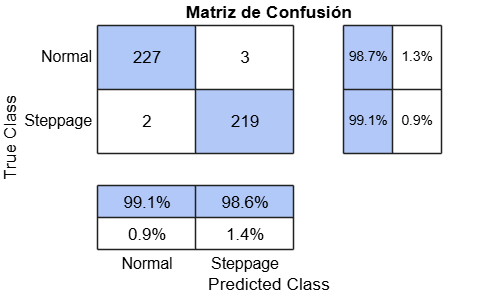

% --- VISUALIZAR RESULTADOS ---
figure('Name', 'Evaluación del Modelo', 'Color', 'w');
cm = confusionchart(Y_test, Y_pred);
cm.Title = 'Matriz de Confusión';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

% 1. Color para las predicciones CORRECTAS (Diagonal)
% Aquí usamos un tono verde amigable
cm.DiagonalColor = [0.690 0.784 0.973]; 

% 2. Color para las predicciones INCORRECTAS (Fuera de la diagonal)
% Aquí usamos un tono rojizo/naranja
cm.OffDiagonalColor = [1 1 1]; 

% 3. (Opcional) Cambiar el color de la fuente para que contraste mejor
cm.FontColor = 'black';
saveas(gcf, '1_Matriz_Confusion.png'); % <--- GUARDAR

% ==========================================
% Cálculo de Precision, Recall y F1-Score
% ==========================================
exactitud = sum(Y_pred == Y_test) / length(Y_test) * 100;

% 1. Definir cuál es la clase "Positiva" (la patología a detectar)
% NOTA: Asegúrate de que el texto coincida exactamente con cómo está escrito en tu tabla
clase_objetivo = 'Steppage'; 

% Verdaderos Positivos (TP): Era Steppage y el modelo diagnosticó Steppage
TP = sum((Y_pred == clase_objetivo) & (Y_test == clase_objetivo));

% Falsos Negativos (FN): Era Steppage pero el modelo diagnosticó Normal
FN = sum((Y_pred ~= clase_objetivo) & (Y_test == clase_objetivo));

% Falsos Positivos (FP): Era Normal pero el modelo diagnosticó Steppage
FP = sum((Y_pred == clase_objetivo) & (Y_test ~= clase_objetivo));

% 2. Calcular las métricas (en formato decimal 0.0 a 1.0)
recall = TP / (TP + FN);
precision = TP / (TP + FP);
f1_score = 2 * (precision * recall) / (precision + recall);

% 3. Imprimir resultados en pantalla (convertidos a porcentaje)
fprintf('======================================\n');

fprintf('  EXACTITUD (Accuracy):  %.2f%%\n', exactitud); % Tu variable anterior

  EXACTITUD (Accuracy):  98.89%


fprintf('  RECALL (Sensibilidad): %.2f%%\n', recall * 100);

  RECALL (Sensibilidad): 99.10%


fprintf('  PRECISIÓN (Precision): %.2f%%\n', precision * 100);

  PRECISIÓN (Precision): 98.65%


fprintf('  F1-SCORE:              %.2f%%\n', f1_score * 100);

  F1-SCORE:              98.87%


fprintf('======================================\n');

% ==========================================
% Extracción de Variables Significativas (Feature Importance)
% ==========================================

% 1. Calcular la importancia basada en el error Out-of-Bag
% Este comando le pregunta al modelo: "¿Qué tanto dependes de cada columna?"
importancia = oobPermutedPredictorImportance(rf_model);

% 2. Crear una tabla para organizar los resultados
importanciaTab = table(X_train.Properties.VariableNames', importancia', ...
    'VariableNames', {'Variable', 'Importancia'});

% 3. Ordenar de mayor a menor importancia
importanciaTab = sortrows(importanciaTab, 'Importancia', 'descend');

% 4. Mostrar el Top 15 en la consola
fprintf('Top 15 Variables más significativas:\n');

Top 15 Variables más significativas:


disp(importanciaTab(1:15, :));

           Variable           Importancia
    ______________________    ___________

    {'RightKnee_Z_Std'   }      0.90137  
    {'RightKnee_Z_Max'   }      0.73538  
    {'RightAnkle_Z_Std'  }      0.71142  
    {'RightKnee_Z_ROM'   }      0.63328  
    {'Head_X_Min'        }      0.62883  
    {'LeftHand_Z_Mean'   }       0.6115  
    {'RightAnkle_Z_Max'  }      0.56344  
    {'Neck_X_Std'        }      0.56166  
    {'RightAnkle_Z_Mean' }      0.56119  
    {'Head_X_Mean'       }      0.50839  
    {'LeftHandTip_Z_Mean'}      0.49334  
    {'Neck_X_Min'        }        0.489  
    {'RightFoot_Z_Std'   }      0.46962  
    {'RightFoot_Z_Mean'  }      0.45502  
    {'LeftWrist_Z_Std'   }      0.44883  



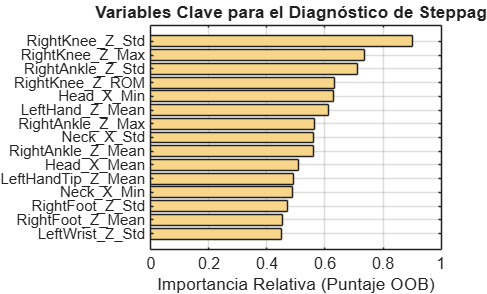


% 5. Graficar los resultados para tu reporte
figure('Name', 'Importancia de Variables', 'Color', 'w');
numMostrar = 15; % Graficaremos las 15 principales
barh(importanciaTab.Importancia(numMostrar:-1:1), 'FaceColor', [0.973 0.839 0.537]);

% 1. Asignar las etiquetas de texto sin el argumento 'Interpreter'
yticklabels(importanciaTab.Variable(numMostrar:-1:1));

xlabel('Importancia Relativa (Puntaje OOB)');
title('Variables Clave para el Diagnóstico de Steppage');
grid on;

% 2. Obtener los ejes actuales
ax = gca;

% Tip: Ajustar márgenes y tamaño de letra
ax.YAxis.FontSize = 9;

% 3. LA SOLUCIÓN: Cambiar el intérprete de las etiquetas de los ejes a 'none'
ax.TickLabelInterpreter = 'none';
saveas(gcf, '2_Importancia_Variables.png');

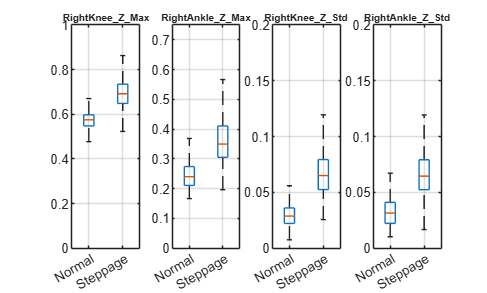

% --- Boxplots de las variables con mayor importancia ---
% Asumiendo que tienes 'tablaMaestra' en el workspace
variables_top = {'RightKnee_Z_Max', 'RightAnkle_Z_Max', 'RightKnee_Z_Std', 'RightAnkle_Z_Std'};

figure('Name', 'Distribución de Características Clave');
for i = 1:length(variables_top)
    subplot(1, 4, i);
    
    % Al agregar 'Symbol', '' le decimos a MATLAB que NO dibuje las cruces rojas (+)
    % Esto permite que la gráfica haga un auto-zoom perfecto a las cajas.
    boxplot(tablaMaestra.(variables_top{i}), tablaMaestra.Clase, 'Symbol', '');
    
    title(variables_top{i}, 'Interpreter', 'none', 'FontSize', 6);
    grid on;
    
    % OPCIONAL: Si aún sin cruces quieres forzar un zoom manual, 
    % puedes descomentar las siguientes líneas y ajustar los números:
    if i == 1
       ylim([0 1]); % Corta la gráfica entre 0 y 3 metros
    elseif i == 2
        ylim([0 0.75]);
    elseif i==3
        ylim([0 0.2]);
    elseif i==4
        ylim([0 0.2]);
    end
end
saveas(gcf, '3_Boxplots_Variables_Top.png'); % <--- GUARDAR

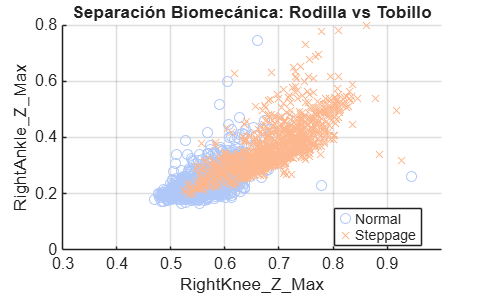

% --- Gráfico de Dispersión: Knee vs Ankle ---
figure('Name', 'Separación de Clases en Espacio de Características', 'Color', 'w');

% 1. Definir los colores RGB personalizados
% Fila 1: Color para la primera clase ('Normal')
% Fila 2: Color para la segunda clase ('Steppage')
colores_rgb = [0.690 0.784 0.973;  % Normal
               0.992, 0.717, 0.561]; % Steppage

% 2. Reemplazar 'br' por la matriz de colores_rgb
gscatter(tablaMaestra.RightKnee_Z_Max, tablaMaestra.RightAnkle_Z_Max, ...
         tablaMaestra.Clase, colores_rgb, 'ox');

xlabel('RightKnee_Z_Max', 'Interpreter', 'none');
ylabel('RightAnkle_Z_Max', 'Interpreter','none');
title('Separación Biomecánica: Rodilla vs Tobillo');
legend('Normal', 'Steppage', 'Location', 'best'); % 'best' ubica la leyenda donde estorbe menos
grid on;

% --- Hacer Zoom para ignorar el outlier ---
xlim([0.3 1]);
ylim([0 0.8]);

saveas(gcf, '4_Scatter_Knee_Ankle.png'); % <--- GUARDAR